% Define the transfer function variable
s = tf('s');

% Given parameters
K = 0.92;
T = 0.414;
tau = 0.09;

% Calculate the required damping ratio and natural frequency
Mp = 0.025; % 2.5% overshoot
zeta = sqrt((log(Mp))^2 / (pi^2 + (log(Mp))^2));
settling_time = 0.7; % 0.7 seconds
omega_n = 4 / (zeta * settling_time);

% Initial guess for Kp based on desired natural frequency
Kp = 0.1;
Ki = 1;

% Plant without delay
G_no_delay = K / (T * s + 1)

G_no_delay =
 
     0.92
  -----------
  0.414 s + 1
 
Continuous-time transfer function.
Model Properties



% Plant with delay using Pade approximation
[n_pade, d_pade] = pade(tau, 1); % Pade approximation of order 1
delay_approx = tf(n_pade, d_pade)

delay_approx =
 
  -s + 22.22
  ----------
  s + 22.22
 
Continuous-time transfer function.
Model Properties



% Plant with delay approximated using Pade
G = G_no_delay * delay_approx

G =
 
       -0.92 s + 20.44
  --------------------------
  0.414 s^2 + 10.2 s + 22.22
 
Continuous-time transfer function.
Model Properties



% Initial P Controller
C = (Kp *s + Ki)/s

C =
 
  0.1 s + 1
  ---------
      s
 
Continuous-time transfer function.
Model Properties



% Closed-loop Transfer Function
Q_s = C * G

Q_s =
 
   -0.092 s^2 + 1.124 s + 20.44
  ------------------------------
  0.414 s^3 + 10.2 s^2 + 22.22 s
 
Continuous-time transfer function.
Model Properties


[num1, den1] = tfdata(Q_s, 'v')

num1 =          0   -0.0920    1.1244   20.4444


den1 =     0.4140   10.2000   22.2222         0


Q_ss = 1 + Q_s

Q_ss =
 
  0.414 s^3 + 10.11 s^2 + 23.35 s + 20.44
  ---------------------------------------
      0.414 s^3 + 10.2 s^2 + 22.22 s
 
Continuous-time transfer function.
Model Properties


[num2, den2] = tfdata(Q_ss, 'v')

num2 =     0.4140   10.1080   23.3467   20.4444


den2 =     0.4140   10.2000   22.2222         0


T_s =  tf( num1 , num2)

T_s =
 
       -0.092 s^2 + 1.124 s + 20.44
  ---------------------------------------
  0.414 s^3 + 10.11 s^2 + 23.35 s + 20.44
 
Continuous-time transfer function.
Model Properties



% Analyze the step response and adjust Kp to achieve the desired specs
info = stepinfo(T_s)

info = struct with fields:
         RiseTime: 1.6864
    TransientTime: 2.6058
     SettlingTime: 2.6066
      SettlingMin: 0.9049
      SettlingMax: 1.0108
        Overshoot: 1.0819
       Undershoot: 0.3609
             Peak: 1.0108
         PeakTime: 3.6590



% Adjust Kp until the criteria are met
while info.Overshoot > 2.5 || info.SettlingTime > 0.7
    Kp = Kp * 1.05; % Increase Kp by 5%
    Ki = Ki * 1.05; % Increase Ki by 10%
    C = (Kp*s+ Ki)/s
    Q_s = C * G;
    [num1, den1] = tfdata(Q_s, 'v');
    Q_ss = 1 + Q_s;
    [num2, den2] = tfdata(Q_ss, 'v');
    T_s =  tf( num1 , num2)% Recalculate T_s
    info = stepinfo(T_s);
end

C =
 
  0.105 s + 1.05
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.0966 s^2 + 1.181 s + 21.47
  -------------------------------------
  0.414 s^3 + 10.1 s^2 + 23.4 s + 21.47
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1103 s + 1.103
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1014 s^2 + 1.24 s + 22.54
  --------------------------------------
  0.414 s^3 + 10.1 s^2 + 23.46 s + 22.54
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1158 s + 1.158
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1065 s^2 + 1.302 s + 23.67
  ---------------------------------------
  0.414 s^3 + 10.09 s^2 + 23.52 s + 23.67
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1216 s + 1.216
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1118 s^2 + 1.367 s + 24.85
  ---------------------------------------
  0.414 s^3 + 10.09 s^2 + 23.59 s + 24.85
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1276 s + 1.276
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1174 s^2 + 1.435 s + 26.09
  ---------------------------------------
  0.414 s^3 + 10.08 s^2 + 23.66 s + 26.09
 
Continuous-time transfer function.
Model Properties


C =
 
  0.134 s + 1.34
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1233 s^2 + 1.507 s + 27.4
  --------------------------------------
  0.414 s^3 + 10.08 s^2 + 23.73 s + 27.4
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1407 s + 1.407
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.1295 s^2 + 1.582 s + 28.77
  --------------------------------------
  0.414 s^3 + 10.07 s^2 + 23.8 s + 28.77
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1477 s + 1.477
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1359 s^2 + 1.661 s + 30.21
  ---------------------------------------
  0.414 s^3 + 10.06 s^2 + 23.88 s + 30.21
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1551 s + 1.551
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1427 s^2 + 1.744 s + 31.72
  ---------------------------------------
  0.414 s^3 + 10.06 s^2 + 23.97 s + 31.72
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1629 s + 1.629
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1499 s^2 + 1.832 s + 33.3
  --------------------------------------
  0.414 s^3 + 10.05 s^2 + 24.05 s + 33.3
 
Continuous-time transfer function.
Model Properties


C =
 
  0.171 s + 1.71
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1574 s^2 + 1.923 s + 34.97
  ---------------------------------------
  0.414 s^3 + 10.04 s^2 + 24.15 s + 34.97
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1796 s + 1.796
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1652 s^2 + 2.019 s + 36.72
  ---------------------------------------
  0.414 s^3 + 10.03 s^2 + 24.24 s + 36.72
 
Continuous-time transfer function.
Model Properties


C =
 
  0.1886 s + 1.886
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1735 s^2 + 2.12 s + 38.55
  ---------------------------------------
  0.414 s^3 + 10.03 s^2 + 24.34 s + 38.55
 
Continuous-time transfer function.
Model Properties


C =
 
  0.198 s + 1.98
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1822 s^2 + 2.226 s + 40.48
  ---------------------------------------
  0.414 s^3 + 10.02 s^2 + 24.45 s + 40.48
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2079 s + 2.079
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.1913 s^2 + 2.338 s + 42.5
  --------------------------------------
  0.414 s^3 + 10.01 s^2 + 24.56 s + 42.5
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2183 s + 2.183
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2008 s^2 + 2.455 s + 44.63
  ---------------------------------------
  0.414 s^3 + 9.999 s^2 + 24.68 s + 44.63
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2292 s + 2.292
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.2109 s^2 + 2.577 s + 46.86
  --------------------------------------
  0.414 s^3 + 9.989 s^2 + 24.8 s + 46.86
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2407 s + 2.407
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2214 s^2 + 2.706 s + 49.2
  --------------------------------------
  0.414 s^3 + 9.979 s^2 + 24.93 s + 49.2
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2527 s + 2.527
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2325 s^2 + 2.841 s + 51.66
  ---------------------------------------
  0.414 s^3 + 9.968 s^2 + 25.06 s + 51.66
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2653 s + 2.653
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2441 s^2 + 2.983 s + 54.25
  ---------------------------------------
  0.414 s^3 + 9.956 s^2 + 25.21 s + 54.25
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2786 s + 2.786
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2563 s^2 + 3.133 s + 56.96
  ---------------------------------------
  0.414 s^3 + 9.944 s^2 + 25.35 s + 56.96
 
Continuous-time transfer function.
Model Properties


C =
 
  0.2925 s + 2.925
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2691 s^2 + 3.289 s + 59.81
  ---------------------------------------
  0.414 s^3 + 9.931 s^2 + 25.51 s + 59.81
 
Continuous-time transfer function.
Model Properties


C =
 
  0.3072 s + 3.072
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2826 s^2 + 3.454 s + 62.8
  --------------------------------------
  0.414 s^3 + 9.917 s^2 + 25.68 s + 62.8
 
Continuous-time transfer function.
Model Properties


C =
 
  0.3225 s + 3.225
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.2967 s^2 + 3.626 s + 65.94
  ---------------------------------------
  0.414 s^3 + 9.903 s^2 + 25.85 s + 65.94
 
Continuous-time transfer function.
Model Properties


C =
 
  0.3386 s + 3.386
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3115 s^2 + 3.808 s + 69.23
  ---------------------------------------
  0.414 s^3 + 9.888 s^2 + 26.03 s + 69.23
 
Continuous-time transfer function.
Model Properties


C =
 
  0.3556 s + 3.556
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3271 s^2 + 3.998 s + 72.69
  ---------------------------------------
  0.414 s^3 + 9.873 s^2 + 26.22 s + 72.69
 
Continuous-time transfer function.
Model Properties


C =
 
  0.3733 s + 3.733
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3435 s^2 + 4.198 s + 76.33
  ---------------------------------------
  0.414 s^3 + 9.857 s^2 + 26.42 s + 76.33
 
Continuous-time transfer function.
Model Properties


C =
 
  0.392 s + 3.92
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3607 s^2 + 4.408 s + 80.14
  ---------------------------------------
  0.414 s^3 + 9.839 s^2 + 26.63 s + 80.14
 
Continuous-time transfer function.
Model Properties


C =
 
  0.4116 s + 4.116
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3787 s^2 + 4.628 s + 84.15
  ---------------------------------------
  0.414 s^3 + 9.821 s^2 + 26.85 s + 84.15
 
Continuous-time transfer function.
Model Properties


C =
 
  0.4322 s + 4.322
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.3976 s^2 + 4.86 s + 88.36
  ---------------------------------------
  0.414 s^3 + 9.802 s^2 + 27.08 s + 88.36
 
Continuous-time transfer function.
Model Properties


C =
 
  0.4538 s + 4.538
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.4175 s^2 + 5.103 s + 92.78
  ---------------------------------------
  0.414 s^3 + 9.783 s^2 + 27.32 s + 92.78
 
Continuous-time transfer function.
Model Properties


C =
 
  0.4765 s + 4.765
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.4384 s^2 + 5.358 s + 97.42
  ---------------------------------------
  0.414 s^3 + 9.762 s^2 + 27.58 s + 97.42
 
Continuous-time transfer function.
Model Properties


C =
 
  0.5003 s + 5.003
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.4603 s^2 + 5.626 s + 102.3
  --------------------------------------
  0.414 s^3 + 9.74 s^2 + 27.85 s + 102.3
 
Continuous-time transfer function.
Model Properties


C =
 
  0.5253 s + 5.253
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.4833 s^2 + 5.907 s + 107.4
  ---------------------------------------
  0.414 s^3 + 9.717 s^2 + 28.13 s + 107.4
 
Continuous-time transfer function.
Model Properties


C =
 
  0.5516 s + 5.516
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.5075 s^2 + 6.202 s + 112.8
  ---------------------------------------
  0.414 s^3 + 9.693 s^2 + 28.42 s + 112.8
 
Continuous-time transfer function.
Model Properties


C =
 
  0.5792 s + 5.792
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.5328 s^2 + 6.513 s + 118.4
  ---------------------------------------
  0.414 s^3 + 9.667 s^2 + 28.73 s + 118.4
 
Continuous-time transfer function.
Model Properties


C =
 
  0.6081 s + 6.081
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.5595 s^2 + 6.838 s + 124.3
  ---------------------------------------
  0.414 s^3 + 9.641 s^2 + 29.06 s + 124.3
 
Continuous-time transfer function.
Model Properties


C =
 
  0.6385 s + 6.385
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.5875 s^2 + 7.18 s + 130.5
  --------------------------------------
  0.414 s^3 + 9.613 s^2 + 29.4 s + 130.5
 
Continuous-time transfer function.
Model Properties


C =
 
  0.6705 s + 6.705
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.6168 s^2 + 7.539 s + 137.1
  ---------------------------------------
  0.414 s^3 + 9.583 s^2 + 29.76 s + 137.1
 
Continuous-time transfer function.
Model Properties


C =
 
  0.704 s + 7.04
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.6477 s^2 + 7.916 s + 143.9
  ---------------------------------------
  0.414 s^3 + 9.552 s^2 + 30.14 s + 143.9
 
Continuous-time transfer function.
Model Properties


C =
 
  0.7392 s + 7.392
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.6801 s^2 + 8.312 s + 151.1
  --------------------------------------
  0.414 s^3 + 9.52 s^2 + 30.53 s + 151.1
 
Continuous-time transfer function.
Model Properties


C =
 
  0.7762 s + 7.762
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.7141 s^2 + 8.727 s + 158.7
  ---------------------------------------
  0.414 s^3 + 9.486 s^2 + 30.95 s + 158.7
 
Continuous-time transfer function.
Model Properties


C =
 
  0.815 s + 8.15
  --------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
      -0.7498 s^2 + 9.164 s + 166.6
  --------------------------------------
  0.414 s^3 + 9.45 s^2 + 31.39 s + 166.6
 
Continuous-time transfer function.
Model Properties


C =
 
  0.8557 s + 8.557
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.7873 s^2 + 9.622 s + 174.9
  ---------------------------------------
  0.414 s^3 + 9.413 s^2 + 31.84 s + 174.9
 
Continuous-time transfer function.
Model Properties


C =
 
  0.8985 s + 8.985
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.8266 s^2 + 10.1 s + 183.7
  ---------------------------------------
  0.414 s^3 + 9.373 s^2 + 32.33 s + 183.7
 
Continuous-time transfer function.
Model Properties


C =
 
  0.9434 s + 9.434
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.868 s^2 + 10.61 s + 192.9
  ---------------------------------------
  0.414 s^3 + 9.332 s^2 + 32.83 s + 192.9
 
Continuous-time transfer function.
Model Properties


C =
 
  0.9906 s + 9.906
  ----------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.9113 s^2 + 11.14 s + 202.5
  ---------------------------------------
  0.414 s^3 + 9.289 s^2 + 33.36 s + 202.5
 
Continuous-time transfer function.
Model Properties


C =
 
  1.04 s + 10.4
  -------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -0.9569 s^2 + 11.7 s + 212.6
  ---------------------------------------
  0.414 s^3 + 9.243 s^2 + 33.92 s + 212.6
 
Continuous-time transfer function.
Model Properties


C =
 
  1.092 s + 10.92
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.005 s^2 + 12.28 s + 223.3
  --------------------------------------
  0.414 s^3 + 9.195 s^2 + 34.5 s + 223.3
 
Continuous-time transfer function.
Model Properties


C =
 
  1.147 s + 11.47
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.055 s^2 + 12.89 s + 234.4
  ---------------------------------------
  0.414 s^3 + 9.145 s^2 + 35.12 s + 234.4
 
Continuous-time transfer function.
Model Properties


C =
 
  1.204 s + 12.04
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.108 s^2 + 13.54 s + 246.2
  ---------------------------------------
  0.414 s^3 + 9.092 s^2 + 35.76 s + 246.2
 
Continuous-time transfer function.
Model Properties


C =
 
  1.264 s + 12.64
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.163 s^2 + 14.22 s + 258.5
  ---------------------------------------
  0.414 s^3 + 9.037 s^2 + 36.44 s + 258.5
 
Continuous-time transfer function.
Model Properties


C =
 
  1.327 s + 13.27
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.221 s^2 + 14.93 s + 271.4
  ---------------------------------------
  0.414 s^3 + 8.979 s^2 + 37.15 s + 271.4
 
Continuous-time transfer function.
Model Properties


C =
 
  1.394 s + 13.94
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.282 s^2 + 15.67 s + 285
  ------------------------------------
  0.414 s^3 + 8.918 s^2 + 37.9 s + 285
 
Continuous-time transfer function.
Model Properties


C =
 
  1.464 s + 14.64
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.346 s^2 + 16.46 s + 299.2
  ---------------------------------------
  0.414 s^3 + 8.854 s^2 + 38.68 s + 299.2
 
Continuous-time transfer function.
Model Properties


C =
 
  1.537 s + 15.37
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.414 s^2 + 17.28 s + 314.2
  --------------------------------------
  0.414 s^3 + 8.786 s^2 + 39.5 s + 314.2
 
Continuous-time transfer function.
Model Properties


C =
 
  1.614 s + 16.14
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.484 s^2 + 18.14 s + 329.9
  ---------------------------------------
  0.414 s^3 + 8.716 s^2 + 40.37 s + 329.9
 
Continuous-time transfer function.
Model Properties


C =
 
  1.694 s + 16.94
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.559 s^2 + 19.05 s + 346.4
  ---------------------------------------
  0.414 s^3 + 8.641 s^2 + 41.27 s + 346.4
 
Continuous-time transfer function.
Model Properties


C =
 
  1.779 s + 17.79
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
         -1.637 s^2 + 20 s + 363.7
  ---------------------------------------
  0.414 s^3 + 8.563 s^2 + 42.23 s + 363.7
 
Continuous-time transfer function.
Model Properties


C =
 
  1.868 s + 18.68
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
         -1.718 s^2 + 21 s + 381.9
  ---------------------------------------
  0.414 s^3 + 8.482 s^2 + 43.23 s + 381.9
 
Continuous-time transfer function.
Model Properties


C =
 
  1.961 s + 19.61
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.804 s^2 + 22.05 s + 401
  -------------------------------------
  0.414 s^3 + 8.396 s^2 + 44.28 s + 401
 
Continuous-time transfer function.
Model Properties


C =
 
  2.059 s + 20.59
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.895 s^2 + 23.16 s + 421
  -------------------------------------
  0.414 s^3 + 8.305 s^2 + 45.38 s + 421
 
Continuous-time transfer function.
Model Properties


C =
 
  2.162 s + 21.62
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -1.989 s^2 + 24.31 s + 442.1
  ---------------------------------------
  0.414 s^3 + 8.211 s^2 + 46.54 s + 442.1
 
Continuous-time transfer function.
Model Properties


C =
 
  2.27 s + 22.7
  -------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.089 s^2 + 25.53 s + 464.2
  ---------------------------------------
  0.414 s^3 + 8.111 s^2 + 47.75 s + 464.2
 
Continuous-time transfer function.
Model Properties


C =
 
  2.384 s + 23.84
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.193 s^2 + 26.81 s + 487.4
  ---------------------------------------
  0.414 s^3 + 8.007 s^2 + 49.03 s + 487.4
 
Continuous-time transfer function.
Model Properties


C =
 
  2.503 s + 25.03
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.303 s^2 + 28.15 s + 511.8
  ---------------------------------------
  0.414 s^3 + 7.897 s^2 + 50.37 s + 511.8
 
Continuous-time transfer function.
Model Properties


C =
 
  2.628 s + 26.28
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.418 s^2 + 29.55 s + 537.4
  ---------------------------------------
  0.414 s^3 + 7.782 s^2 + 51.78 s + 537.4
 
Continuous-time transfer function.
Model Properties


C =
 
  2.76 s + 27.6
  -------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.539 s^2 + 31.03 s + 564.2
  ---------------------------------------
  0.414 s^3 + 7.661 s^2 + 53.25 s + 564.2
 
Continuous-time transfer function.
Model Properties


C =
 
  2.898 s + 28.98
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.666 s^2 + 32.58 s + 592.4
  ---------------------------------------
  0.414 s^3 + 7.534 s^2 + 54.81 s + 592.4
 
Continuous-time transfer function.
Model Properties


C =
 
  3.043 s + 30.43
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.799 s^2 + 34.21 s + 622.1
  ---------------------------------------
  0.414 s^3 + 7.401 s^2 + 56.44 s + 622.1
 
Continuous-time transfer function.
Model Properties


C =
 
  3.195 s + 31.95
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -2.939 s^2 + 35.92 s + 653.2
  ---------------------------------------
  0.414 s^3 + 7.261 s^2 + 58.15 s + 653.2
 
Continuous-time transfer function.
Model Properties


C =
 
  3.355 s + 33.55
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.086 s^2 + 37.72 s + 685.8
  ---------------------------------------
  0.414 s^3 + 7.114 s^2 + 59.94 s + 685.8
 
Continuous-time transfer function.
Model Properties


C =
 
  3.522 s + 35.22
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.24 s^2 + 39.61 s + 720.1
  --------------------------------------
  0.414 s^3 + 6.96 s^2 + 61.83 s + 720.1
 
Continuous-time transfer function.
Model Properties


C =
 
  3.698 s + 36.98
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.402 s^2 + 41.59 s + 756.1
  ---------------------------------------
  0.414 s^3 + 6.798 s^2 + 63.81 s + 756.1
 
Continuous-time transfer function.
Model Properties


C =
 
  3.883 s + 38.83
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.573 s^2 + 43.67 s + 793.9
  ---------------------------------------
  0.414 s^3 + 6.627 s^2 + 65.89 s + 793.9
 
Continuous-time transfer function.
Model Properties


C =
 
  4.077 s + 40.77
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.751 s^2 + 45.85 s + 833.6
  ---------------------------------------
  0.414 s^3 + 6.449 s^2 + 68.07 s + 833.6
 
Continuous-time transfer function.
Model Properties


C =
 
  4.281 s + 42.81
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -3.939 s^2 + 48.14 s + 875.3
  ---------------------------------------
  0.414 s^3 + 6.261 s^2 + 70.36 s + 875.3
 
Continuous-time transfer function.
Model Properties


C =
 
  4.495 s + 44.95
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -4.136 s^2 + 50.55 s + 919.1
  ---------------------------------------
  0.414 s^3 + 6.064 s^2 + 72.77 s + 919.1
 
Continuous-time transfer function.
Model Properties


C =
 
  4.72 s + 47.2
  -------------
        s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -4.343 s^2 + 53.08 s + 965
  ------------------------------------
  0.414 s^3 + 5.857 s^2 + 75.3 s + 965
 
Continuous-time transfer function.
Model Properties


C =
 
  4.956 s + 49.56
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -4.56 s^2 + 55.73 s + 1013
  -------------------------------------
  0.414 s^3 + 5.64 s^2 + 77.95 s + 1013
 
Continuous-time transfer function.
Model Properties


C =
 
  5.204 s + 52.04
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_s =
 
       -4.788 s^2 + 58.52 s + 1064
  --------------------------------------
  0.414 s^3 + 5.412 s^2 + 80.74 s + 1064
 
Continuous-time transfer function.
Model Properties



% Display the final value of Kp
fprintf('Final value of Kp: %.4f\n', Kp);

Final value of Kp: 5.2040


fprintf('Final value of Ki: %.4f\n', Ki);

Final value of Ki: 52.0395


info = stepinfo(T_s);


% Display the step response characteristics
disp(info);

         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf



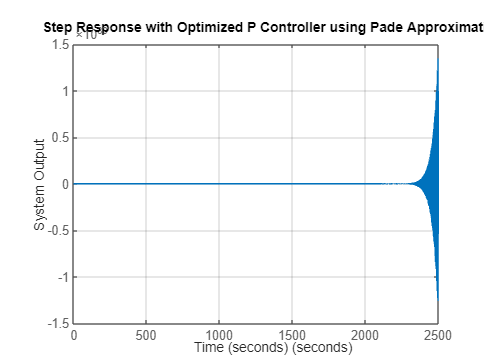


% Plot the final step response
figure;
step(T_s);
title('Step Response with Optimized P Controller using Pade Approximation');
xlabel('Time (seconds)');
ylabel('System Output');
grid on;